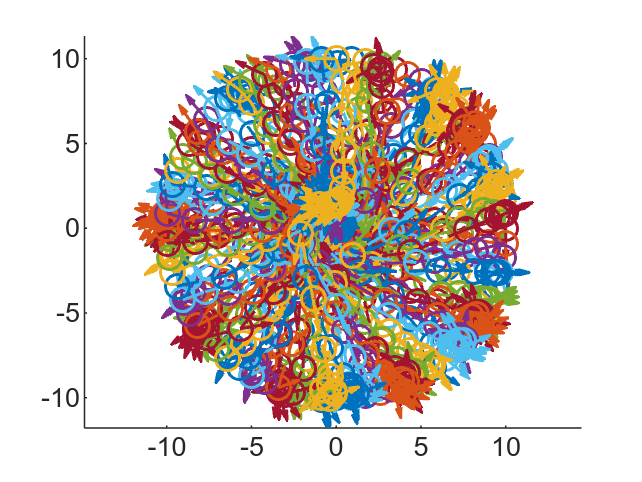

clear, clc, close all

% stable and unstable equibilim points problem
car1 = carModel(0,0,pi/2,[0,4]);
car2 = carModel(0,4,-pi/2,[0,0]);
car3 = carModel(-1,0,pi/2,[1,4]);
car4 = carModel(-2,2,0,[2,2]);
car5 = carModel(3,0,pi,[-1,4]);

carArr = {car1; car2};
carArr = {car1; car2; car3; car4; car5};

x0 = 0;
x1 = 0.8;
A = [0 0 0 1;
    x1^3 x1^2 x1^1 1;
    3*x1^2 2*x1 1 0;
    6*x1 2 0 0];
b = [0.3; 0; 0; 0];
a_i = A \ b;

% generate cars on watch face
dtheta = 5;
r = 10;
dt = 0.30;
T = 900;
for i = 1:(360/dtheta)
    theta = dtheta * i * pi / 180;
    x = r * sin(theta);
    y = r * cos(theta);
    direction = theta + pi;
    goalx = r * sin(direction);
    goaly = r * cos(direction);
    carArr{i} = carModel(x, y, direction, [goalx, goaly], dt, true, T);
end

for i = 1:carArr{1}.T
    for j = 1:length(carArr)

        [v_nominal, omega_nominal] = carArr{j}.getPorpotionalcontrol();
        V_filtered = carArr{j}.RCBF_Filter_nearest_circulation_soft(carArr, j, [v_nominal; omega_nominal]);
        % V_filtered = carArr{j}.RCBF_Filter_nearest_circulation(carArr, j, [v_nominal; omega_nominal]);

        carArr{j}.updateState(V_filtered);
    end
end

figure
hold on
for i = 1:length(carArr)
    carArr{i}.plotHistory()
end
axis equal
hold off

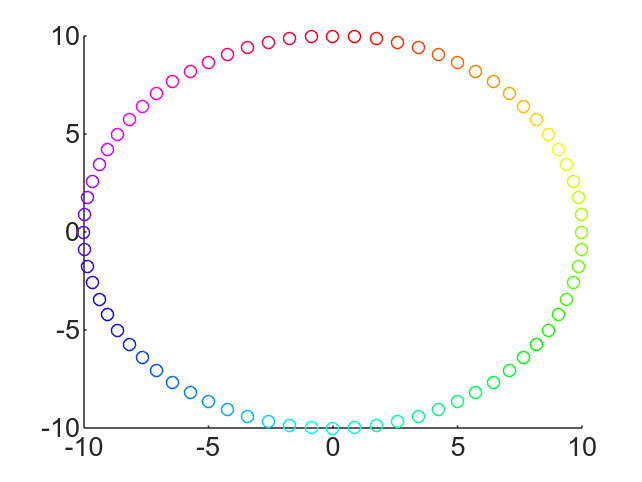

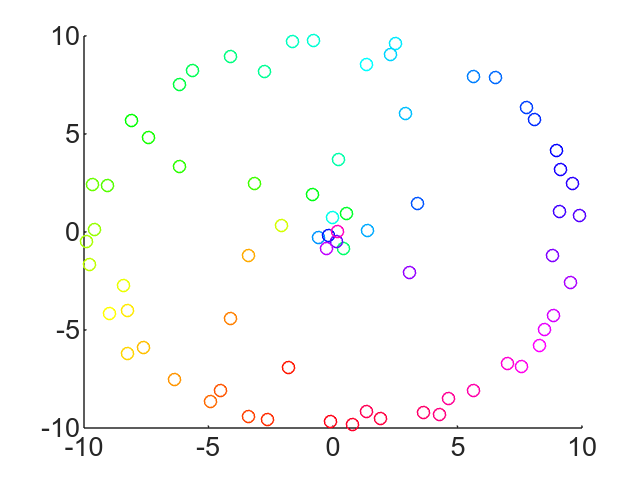


figure
cmap = hsv(length(carArr));
stepInterval = 10;
for i = 1:stepInterval:carArr{1}.T-1
    clf
    hold on
    for j = 1:length(carArr)
        plot(carArr{j}.history(i,1), carArr{j}.history(i,2),"LineStyle","none","Marker","o","MarkerSize",4, "Color", cmap(j, :))
    end
    xlim([-10 10])
    ylim([-10 10])
    pause(0.1)
    hold off
end